load("task_rmse_tables.mat")

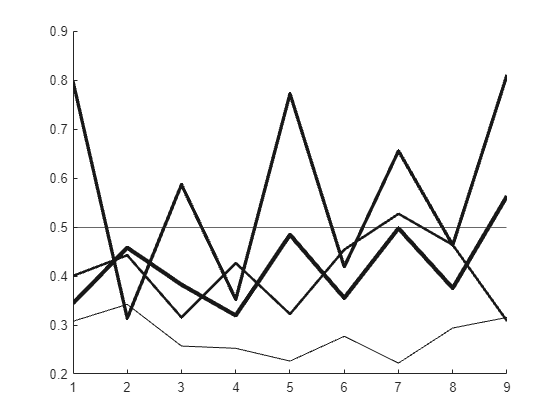

figure
THEME.BLACK = [0.0941, 0.0941, 0.0941];
THEME.BLUE = [0.0510, 0.2078, 0.5020];
THEME.RED = [0.8235, 0.1608, 0.1765];
THEME.WIDTH = 2.5;
hold on
rmse_all = [];
for i=1:length(participant)
    rmse_data = participant(i).hl_expl_rmse_tbl.INT(:,1);
    plot(rmse_data, Color=THEME.BLACK, LineWidth=THEME.WIDTH*0.25*i);
    rmse_all = [rmse_all, rmse_data];
end
plot(mean(rmse_all, 2), Color=THEME.RED, LineWidth=THEME.WIDTH*1.25)
plot(mean(rmse_all, 2)+std(rmse_all, 0,2), '--', Color=THEME.RED, LineWidth=THEME.WIDTH*0.75)
plot(mean(rmse_all, 2)-std(rmse_all, 0,2), '--', Color=THEME.RED, LineWidth=THEME.WIDTH*0.75)
% ylim([0 0.5])
yline(0.5)
hold off 
box off